# EXERCISE #2 : Build the Simplest WLAN Network

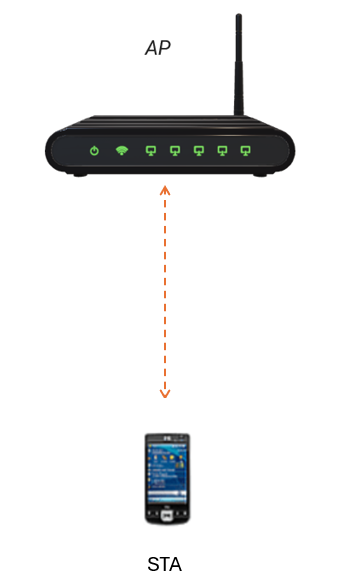

WLAN Network with one AP and one STA 

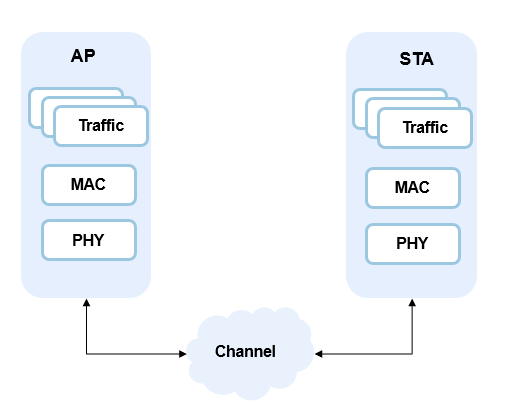

Modeled Blocks 

#### In this exercise, You will learn how to  

- Configure and create WLAN nodes and networks

- Simulate the WLAN network and capture statistics

- Visualize the WLAN and Bluetooth data link layer state transitions

- Analyze WLAN network performance under Bluetooth interference

Copyright 2024-2025 The MathWorks, Inc

#### Cleanup

clear;
format default
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 

### General settings

- `2.4 GHz band`

- `20 MHz wide channel`

- `Channel 7`

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html)

band        = 2.4;
bandwidth   = 20e6;
channel     = 7;
fc          = wlanChannelFrequency(channel,band);
txPower     = 0.0; % dBm - Use 0 dBm to make calculations easy. The received power is equal to negative of path loss. 
txGain      = 0.0; % dB  - Will use this field to mimic additional attenuation

- `Time Unit = 1024us`

TU              = 1024e-6; % Time Unit(TU) in WLAN is 1024 us 
simulationTime  = 100*TU;  % Simulation time is set to 100*TU 

### Geometry

- Define position of AP and STA

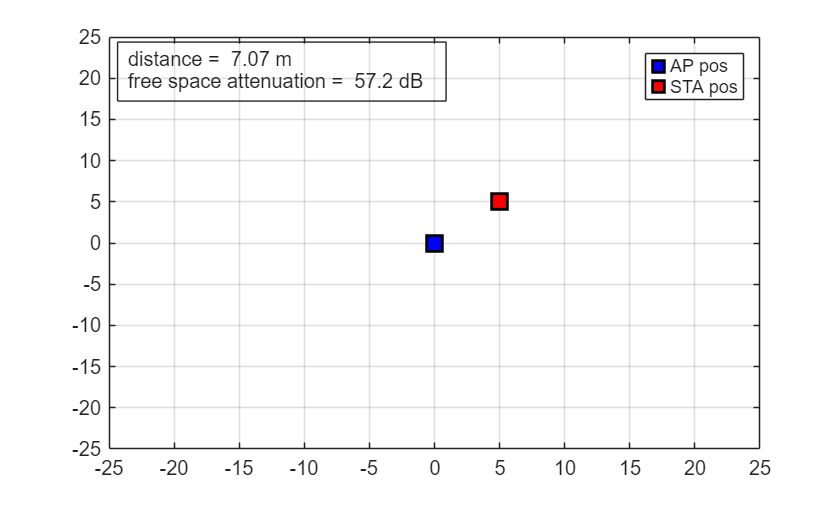

% Adjust relative positions of AP and STA to change SNR
% range -15m, +15m in X and Y (limited by plotStations utility function, but could be updated if needed)
AP_pos  = [0,0,0];
STA_pos = [5,5,0];
% Utility function to plot AP, STA, distance and fspl
[dist, atten] = plotNodesPositions(AP_pos,STA_pos,fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

#### Select Interference Modeling Options

interferenceModeling = "non-overlapping-adjacent-channel";  
maxInterferenceOffset = 0;

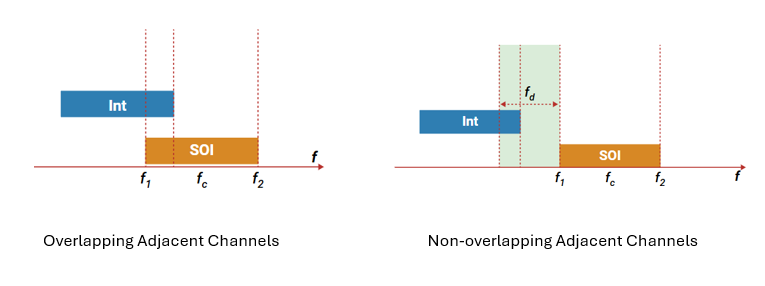

#### Enable or Disable Aggregation 

enableAggregation = true;

# Task #1/4 Create a Device Configuration for WLAN AP

- 802.11n type

- Sends a beacon each 10x TU (10.24 ms)

- AP is located at [0, 0, 0]

% Use wlanDeviceConfig() function to configure the AP
% Write configuration in a variable named "APCfg"
% Hint: Type "doc wlanDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% "BandAndChannel",[band,channel]
% "ChannelBandwidth",bandwidth
% "TransmissionFormat","HT-Mixed"
% "TransmitPower",txPower
% "TransmitGain",txGain
% "BeaconInterval",10
% "Mode","AP"
% "MCS",6
% "AggregateHTMPDU",enableAggregation
% "InterferenceModeling",interferenceModeling
% "InitialBeaconOffset",1 

% <enter code below>
APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat", "HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",txPower, ...    
    "TransmitGain",txGain, ...
    "MCS",6, ...
    "AggregateHTMPDU",enableAggregation, ...
    "BeaconInterval", 10, ...
    "InitialBeaconOffset",1, ...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset", ...
    maxInterferenceOffset);
     

Get total attenuation is TransmitGain has been set to a value different from 0

totalAttenuation = atten - APCfg.TransmitGain

totalAttenuation = 57.1864

macabstraction = false;
phyabstraction = "none";

# Task #2/4 Create a WLAN node with AP Configurations  

Note: All nodes on the network must have same MAC and PHY abstractions  

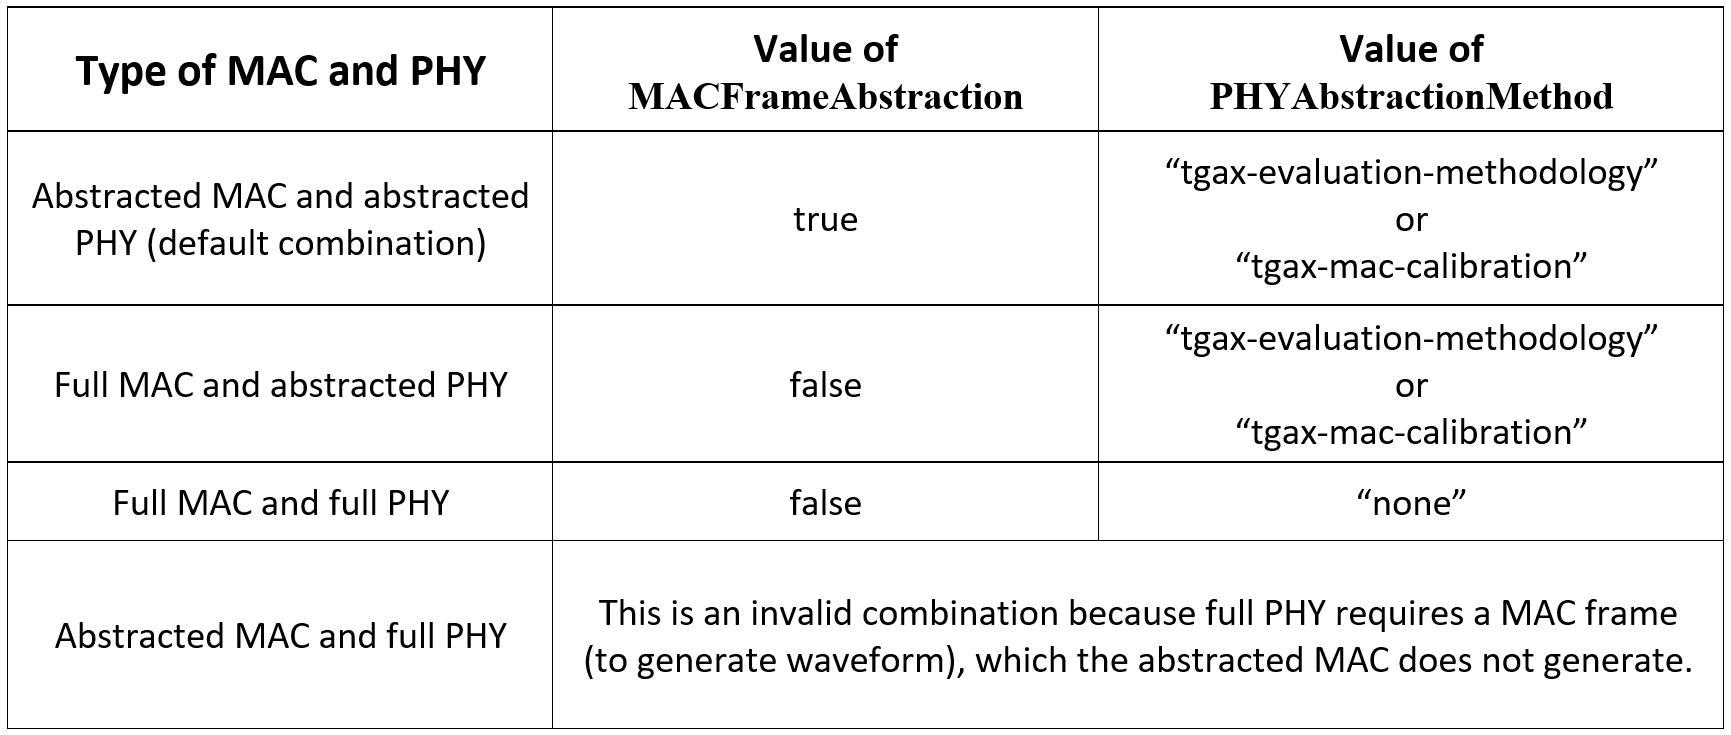

% Use wlanNode() function to instantiate the AP using the configuration you
% have just created
% Name the variable "AP"
% Note : use the following values to start with
% "DeviceConfig",APCfg
% "Position", AP_pos
% "PHYAbstractionMethod",phyabstraction
% "MACFrameAbstraction",macabstraction

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

% <enter code below>
AP = wlanNode(...
    "Name","AP",...
    "Position",AP_pos, ...
    "DeviceConfig",APCfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction); 

### Create the STA

- 802.11n type

- Similar as the creation of the AP

- Code is provided for you

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ... 
    "AggregateHTMPDU",enableAggregation, ...
    "MCS",6, ...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset",maxInterferenceOffset ...
    );

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction);

# Task #3/4 Associate AP with STA

### Define traffic type

- Beacon Only (default)

- Bidirectional

- DL

- UL 

fullBufferTrafficType = "DL"

fullBufferTrafficType = "DL"

`Note`` : `

- `As of now, Full buffer configuration generates traffic in AC0.`

- `As full buffer configuration generates AC0(Best Effort) traffic, you can still instantiate traffic of other ACs (AC1(Background), AC2(Video), AC3(`Voice`))  `

- `Traffic generation is implementation dependent and not part of EDCA and QoS. EDCA and QoS define how the generated traffic is differentiated, prioritized, and queued. `

- `Full buffer just represents a traffic pattern where a node always has data to send at any point of time. This pattern can be applied for any Access Category, but we support it for only AC0 in our simulation.`

% Use associateStations() function to define associations between AP's and STA's
% Hint: Click the link below and and see the "Syntax" section.

### [Help on Associating Station ](https://www.mathworks.com/help/wlan/ref/wlannode.associatestations.html)

% AssociateStations is a method of the wlanNode object
% Note : please use "FullBufferTraffic" = trafficType in the function call

associateStations(AP,STA,"FullBufferTraffic",fullBufferTrafficType);

PeriodicTrafficType = "off"

PeriodicTrafficType = "off"

if strcmp(PeriodicTrafficType, "on") && strcmp(fullBufferTrafficType, "off")
    ap2staTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=350,PacketSize=200);
    addTrafficSource(AP,ap2staTraffic,DestinationNode=STA);

    sta2apTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=350,PacketSize=200);
    addTrafficSource(STA,sta2apTraffic,DestinationNode=AP);
    plotTrafficPattern(simulationTime,ap2staTraffic)
end

#### Introduce **Bluetooth interference** into the simulation to study coexistence effects

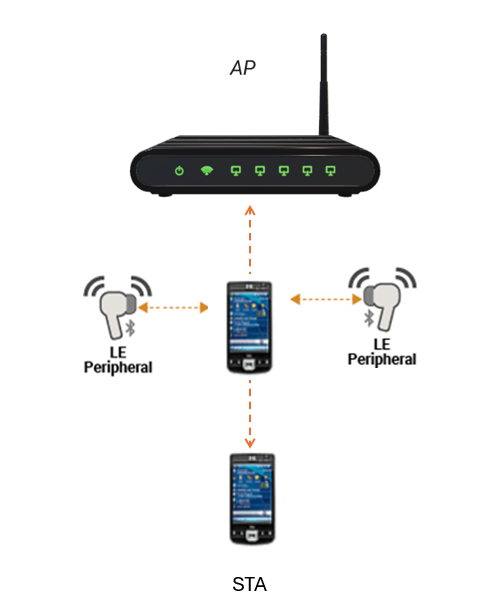

enableBluetoothLEInterference = true;
if enableBluetoothLEInterference
    % Create a Bluetooth LE Central node as an interferer
    source = bluetoothLENode("central","Name","Interferer-1",Position=[1,0,0],TransmitterPower=0, TransmitterGain=0,ReceiverGain=0,ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling,MaxInterferenceOffset=maxInterferenceOffset);
    % Create a Bluetooth LE Peripheral node as an interferer
    leftSink = bluetoothLENode("Peripheral", Position=[3.2,3,0],Name="interferer-2",TransmitterPower=0, TransmitterGain=0, ReceiverGain=0,ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling,MaxInterferenceOffset=maxInterferenceOffset);
    % Create another Bluetooth LE Peripheral node as an interferer
    rightSink = bluetoothLENode("Peripheral", Position=[3,3,0],Name="interferer-3",TransmitterPower=0,TransmitterGain=0,ReceiverGain=0, ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling);
    % Configure Bluetooth LE multicast audio
    cfgCIS = bluetoothLECISConfig(ISOInterval=0.050,NumSubevents=9,BurstNumber=9,SubInterval= 2.5e-3,MaxPDU= 251,FlushTimeout= 1,TMSS= 150e-6,TIFS= 150e-6);
    % Configure a Bluetooth LE connection for control packets
    cfgConnection = bluetoothLEConnectionConfig(ConnectionInterval=0.1,ActivePeriod=0.001,MaxPDU=27,PHYMode="LE2M");
    % Configure a Bluetooth LE connection for control packets
    cfgConnection.AccessAddress = "5DA44270"; cfgConnection.ConnectionOffset = 0; [leftConnCfg,leftCISCfg] = configureConnection(cfgConnection,source,leftSink,CISConfig=cfgCIS);
    cfgConnection.AccessAddress = "5DA44271"; cfgConnection.ConnectionOffset = 0.05; [rightConnCfg,rightCISCfg] = configureConnection(cfgConnection,source,rightSink,CISConfig=cfgCIS);
    % Add Bluetooth audio traffic
    leftSinkTraffic = networkTrafficOnOff(DataRate=320,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
    rightSinkTraffic = networkTrafficOnOff(DataRate=320,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
    addTrafficSource(source,leftSinkTraffic,DestinationNode=leftSink,CISConfig=leftCISCfg);
    addTrafficSource(source,rightSinkTraffic,DestinationNode=rightSink,CISConfig=rightCISCfg);
    intBluetoothLENodes = [source leftSink rightSink];
end

#### **Add nodes to the network **

wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)

**Add Bluetooth nodes to the network **

if enableBluetoothLEInterference 
    addNodes(networkSimulator,intBluetoothLENodes);
end
nodes = networkSimulator.Nodes;

**Enable PCAP capture**

enablePCAPCapture = true;
if enablePCAPCapture
    capturePacketsObj = hExportWLANPackets(wlanNodes, 'pcap', true);
end

#### Enable capture of IQ samples

enableIQCapture  = true;
if enableIQCapture
    iqSampleObj = helperCaptureIQSamples(AP);
end

#### Add channel model to the simulator

channelModel = "TGAX";
if strcmp(channelModel,"TGAX")
    channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
    addChannelModel(networkSimulator,channel.ChannelFcn);
end

#### Enable packet visualization

enablePacketVisualization = true; 
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=enablePacketVisualization);
end

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

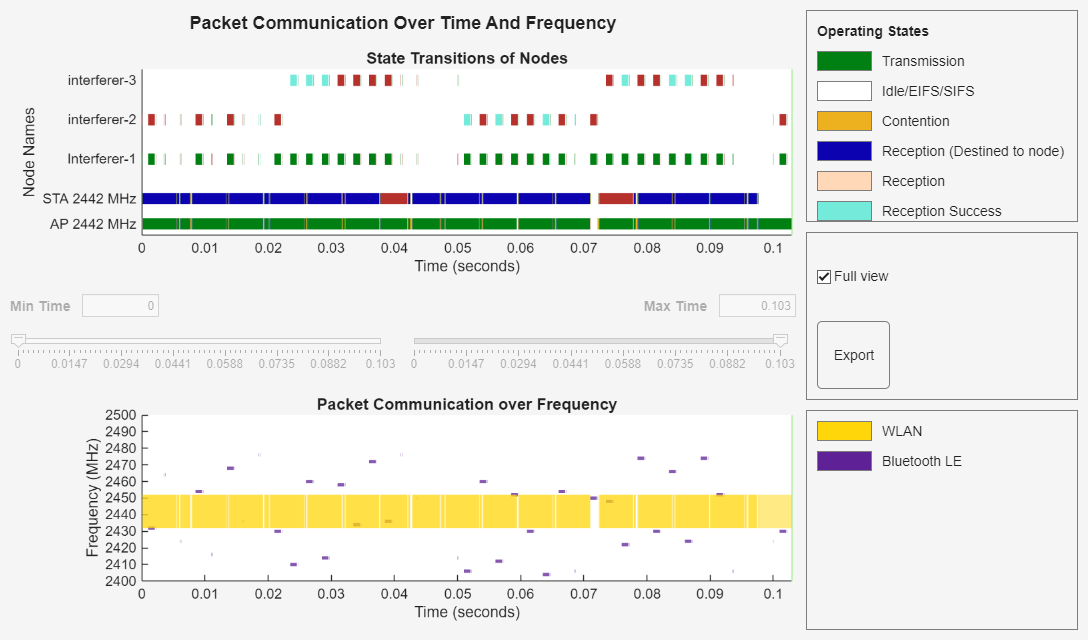

% Create node performance visualization object
perfViewerObj = hPerformanceViewer(wlanNodes,simulationTime);
run (networkSimulator,simulationTime)

# Task #4/4 Display Statistics at AP

% Use statistics() function to get statistics (APP, MAC, PHY) for AP and STA
% Create a variable names APStatistics 
% Hint:  click the link below see the "Syntax" section.

### [Help on statistics](https://www.mathworks.com/help/wlan/ref/wlannode.statistics.html)

% <enter code below>
APStatistics = statistics(AP,"all")

APStatistics = struct with fields:
    Name: "AP"
      ID: 1
     App: [1×1 struct]
     MAC: [1×1 struct]
     PHY: [1×1 struct]
    Mesh: [1×1 struct]


#### APP layer statistics

APStatistics.App

ans = struct with fields:
    TransmittedPackets: 531
      TransmittedBytes: 796500
       ReceivedPackets: 0
         ReceivedBytes: 0
          Destinations: [1×1 struct]


#### MAC layer Statistics

APStatistics.MAC

ans = struct with fields:
            TransmittedDataFrames: 433
          TransmittedPayloadBytes: 412500
      SuccessfulDataTransmissions: 275
          RetransmittedDataFrames: 133
                TransmittedAMPDUs: 21
             TransmittedRTSFrames: 21
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 0
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 0
           TransmittedCFEndFrames: 0
    TransmittedBasicTriggerFrames: 0
          TransmittedBeaconFrames: 10
               ReceivedDataFrames: 0
             ReceivedPayloadBytes: 0
                   ReceivedAMPDUs: 0
                ReceivedRTSFrames: 0
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 21
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 16
              ReceivedCFEndFrames: 0
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames

#### PHY layer Statistics

APStatistics.PHY

ans = struct with fields:
         TransmittedPackets: 52
    TransmittedPayloadBytes: 667576
            ReceivedPackets: 37
       ReceivedPayloadBytes: 806
             DroppedPackets: 20


#### Explore statistics at the STA

STAStatistics = statistics(STA);
STAStatistics.PHY

ans = struct with fields:
         TransmittedPackets: 39
    TransmittedPayloadBytes: 870
            ReceivedPackets: 51
       ReceivedPayloadBytes: 629178
             DroppedPackets: 18


STAStatistics.MAC

ans = struct with fields:
            TransmittedDataFrames: 0
          TransmittedPayloadBytes: 0
      SuccessfulDataTransmissions: 0
          RetransmittedDataFrames: 0
                TransmittedAMPDUs: 0
             TransmittedRTSFrames: 0
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 21
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 18
           TransmittedCFEndFrames: 0
    TransmittedBasicTriggerFrames: 0
          TransmittedBeaconFrames: 0
               ReceivedDataFrames: 320
             ReceivedPayloadBytes: 480000
                   ReceivedAMPDUs: 18
                ReceivedRTSFrames: 21
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 0
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 0
              ReceivedCFEndFrames: 0
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames: 351

STAStatistics.App

ans = struct with fields:
    TransmittedPackets: 0
      TransmittedBytes: 0
       ReceivedPackets: 275
         ReceivedBytes: 412500


#### Calculate throughput, packet loss ratio,latency at nodes 

% Calculate throughput (Mbps) at Nodes
throughputs = throughput(perfViewerObj,[wlanNodes(:).ID])

throughputs =    32.2266         0


% Calculate packet loss ratio at Nodes
packetLossRatio = packetLossRatio(perfViewerObj,[wlanNodes(:).ID])

packetLossRatio =     0.3072       NaN


% Calculate Latency (Seconds) at Nodes
averageReceiveLatency = averageReceiveLatency(perfViewerObj,[wlanNodes(:).ID])

averageReceiveLatency =          0    0.0461


if enablePCAPCapture
    delete(capturePacketsObj.PCAPObjList);
end

#### IQ sample visualization

if enableIQCapture
    signalAnalyzer(iqSampleObj.IQSamples.Data,SampleRate=20e6);
end